Кабанов Степан. Домашняя работа по теме "Экстремумы"

Номер 1

а)

global par T;

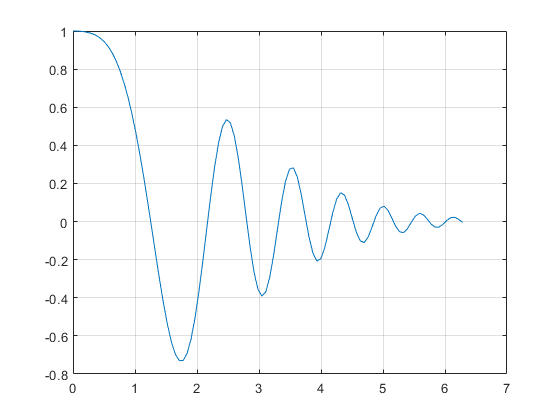

Error using ginput (line 84)
Interrupted by figure deletion

T = '0';
par = 0.1;
N = 100; L1 = 0; L2 = 2*pi; X = linspace(L1,L2,N);
Y = firstTask(X);
plot(X,Y); grid on;
xr = ginput(2);

[x_m, y_m] = fminbnd(@firstTask, xr(1,1), xr(2,1));
hold on;
plot(x_m,y_m,'r*',xr(1,1), xr(1,2),'g*', xr(2,1), xr(2,2), 'g*')
hold off;

b)

clear;
global a1 b1;
T = '0';
a1 = 1;
b1 = 5;
N = 100; L1 = 1; L2 = 2; X = linspace(L1,L2,N);
Y = secondTask(X);
plot(X,Y); grid on;
xr = ginput(2);
[x_m, y_m] = fminbnd(@secondTask, xr(1,1), xr(2,1));
hold on;
plot(x_m,y_m,'r*',xr(1,1), xr(1,2),'g*', xr(2,1), xr(2,2), 'g*')
hold off;

c)

clear;
T = '0';
N = 100; L1 = 0; L2 = 4; X = linspace(L1,L2,N);
Y = thirdTask(X);
plot(X,Y); grid on;
xr = ginput(2);
[x_m, y_m] = fminbnd(@thirdTask, xr(1,1), xr(2,1));
hold on;
plot(x_m,y_m,'r*',xr(1,1), xr(1,2),'g*', xr(2,1), xr(2,2), 'g*')
hold off;

d) Эта секция не работает, так как я не разобрался с рядами

Номер 2.

"Исследовать в зависимости от параметров значение экстремумов функции"

а) f(x)  = x^a * ln(x)

clf;
T = '0';
global alpha;
N = 100; L1 = 0; L2 = 1; X = linspace(L1,L2,N);
hold on;
for i = 1:1:12
    alpha = i
    Y = num2a(X);
    plot(X,Y); grid on;
    xr = [[0 0];[1 0]];
    [x_m, y_m] = fminbnd(@num2a, xr(1,1), xr(2,1));
    plot(x_m,y_m,'r*',xr(1,1), xr(1,2),'g*', xr(2,1), xr(2,2), 'g*')
end

alpha = 1

alpha = 2

alpha = 3

alpha = 4

alpha = 5

alpha = 6

alpha = 7

alpha = 8

alpha = 9

alpha = 10

alpha = 11

alpha = 12

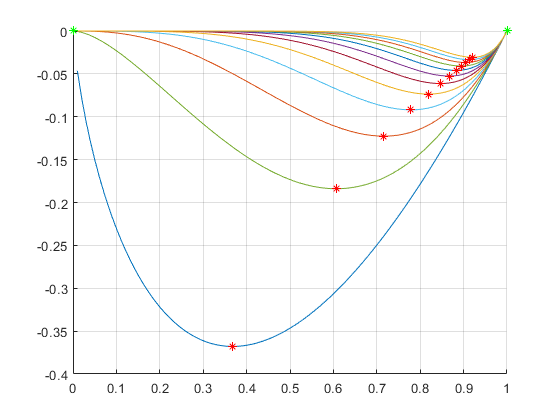

hold off;

b) f(x) = x^a*exp(-beta*x) a, b - parameters

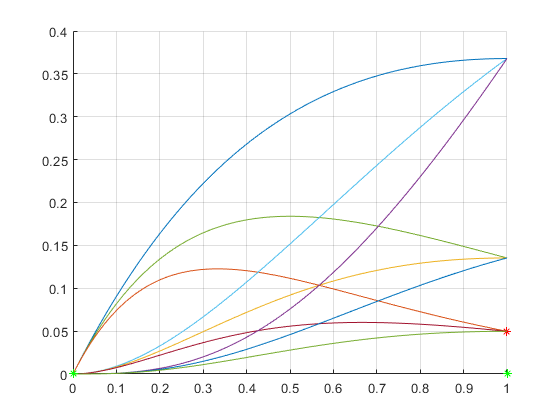

clf;
T = '0';
global alpha beta;
N = 100; L1 = 0; L2 = 1; X = linspace(L1,L2,N);
hold on;
for i = 1:1:3
    for j = 1:1:3
        alpha = i;
        beta = j;
        Y = num2b(X);
        plot(X,Y); grid on;
        xr = [[0 0];[1 0]];
        [x_m, y_m] = fminbnd(@num2b, xr(1,1), xr(2,1));
        plot(x_m,y_m,'r*',xr(1,1), xr(1,2),'g*', xr(2,1), xr(2,2), 'g*')
    end
end
hold off;

c) f(x) = (x^a) * (1 - x)^b

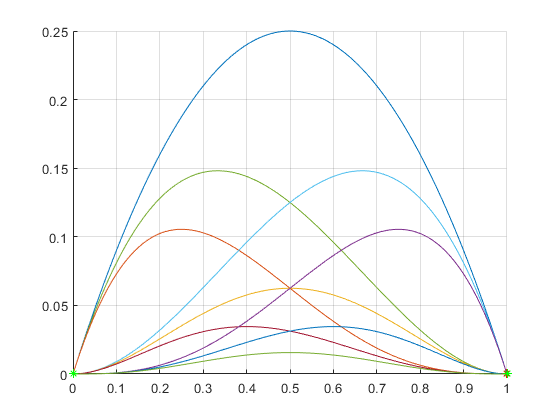

clf;
T = '0';
global alpha beta;
N = 100; L1 = 0; L2 = 1; X = linspace(L1,L2,N);
hold on;
for i = 1:1:3
    for j = 1:1:3
        alpha = i;
        beta = j;
        Y = num2c(X);
        plot(X,Y); grid on;
        xr = [[0 0];[1 0]];
        [x_m, y_m] = fminbnd(@num2c, xr(1,1), xr(2,1));
        plot(x_m,y_m,'r*',xr(1,1), xr(1,2),'g*', xr(2,1), xr(2,2), 'g*')
    end
end
hold off;

3. Изучить функцию fminsearch. Чем она отличается от fminbnd?

Ответ:

Функция fminbnd ищет наименьшее значение функции на промежутке, при заданных границах промежутка. Тогда как функция fminsearch будет сходиться к минимуму при заданной стартовой точке. Очевидно, эти функции используют разные алгоритмы.

4. Какую дополнительную информацию можно получить с помощью функции optimset?

Ответ:

С помощью данной функции можно 